# Walking Arm Trebuchet - Regime 2 Impact Analysis

**Original Author:** Charlie Refvem

**Last Modified:** 05/04/2020

**Description**:

This function analyzes the impact of the walking arm trebuchet with the ground. The function relates the state of the system just before impact (JBI) to the state of the system just after impact, (JAI). This relationship is determined by considering the principle of impulse and momentum during the impact when point A hits the ground.

Three seperate equations will be required to relate the three angular velocities just after impact to the three angular velocities just before impact. These three equations are found by stragetically using the principle of impulse and moment for three different subsets of the mechanism.

## Equation 1

Equation 1 is found by applying the principle of impulse and momentum to the entire mechanism and then summing moments about the contact point A. This will avoid reaction forces at point A from showing up in Equation 1.

**System: **Link 1, Link 2, and Link 3

**JBI:** Before impact, point D is in contact with the ground and remains fixed.

**JAI:** After impact, point A is in contact with the ground and remains fixed.

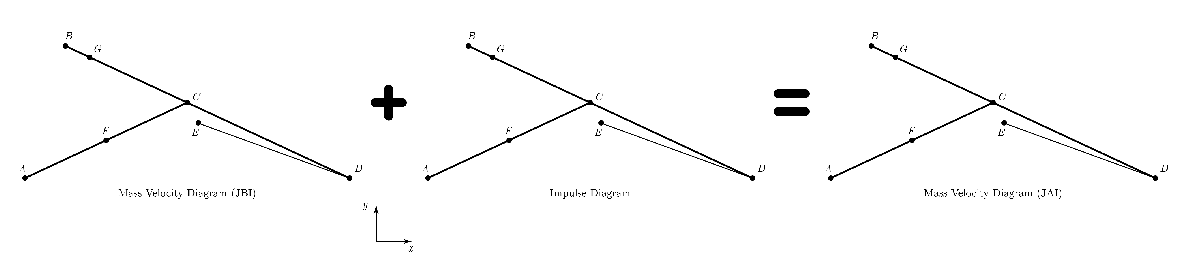


$$\begin{array}{rl l}
\vec{H}_{A\,(JBI)} + \int_{JBI}^{JAI} M_A\, dt &= \vec{H}_{A\, (JAI)} & \\
\vec{H}_{A\,(JBI)} &= \vec{H}_{A\, (JAI)} & \text{(1)}
\end{array}$$


## Equation 2

Equation 2 is found by applying the principle of impulse and momentum to just links 2 and 3 and then summing moments about point C. This will avoid reaction forces at point C from showing up in Equation 2.

**System: **Link 2, and Link 3

**JBI:** Before impact, point D is in contact with the ground and remains fixed.

**JAI:** After impact, point A is in contact with the ground and remains fixed.

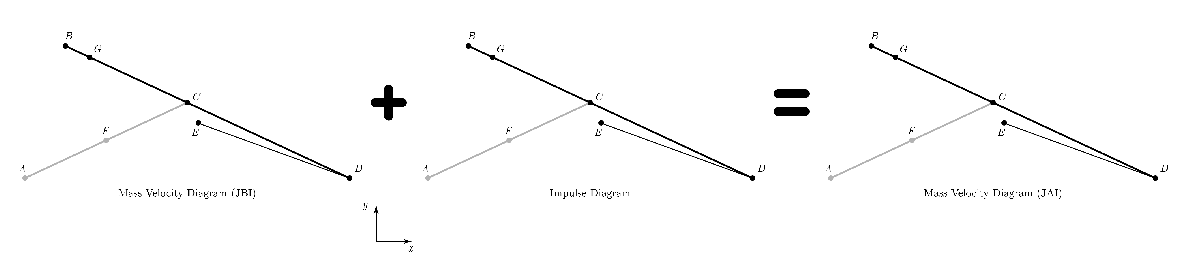


$$\begin{array}{rll}
\vec{H}_{C\,(JBI)} + \int_{JBI}^{JAI} M_C\, dt &= \vec{H}_{C\, (JAI)} & \\
\vec{H}_{C\,(JBI)}  &= \vec{H}_{C\, (JAI)} & \text{(2)}
\end{array}$$


## Equation 3

Equation 3 is found by applying the principle of impulse and momentum to just link 3 and then summing moments about point D. This will avoid reaction forces at point D from showing up in Equation 3.

**System: **Link 3

**JBI:** Before impact, point D is in contact with the ground and remains fixed.

**JAI:** After impact, point A is in contact with the ground and remains fixed.

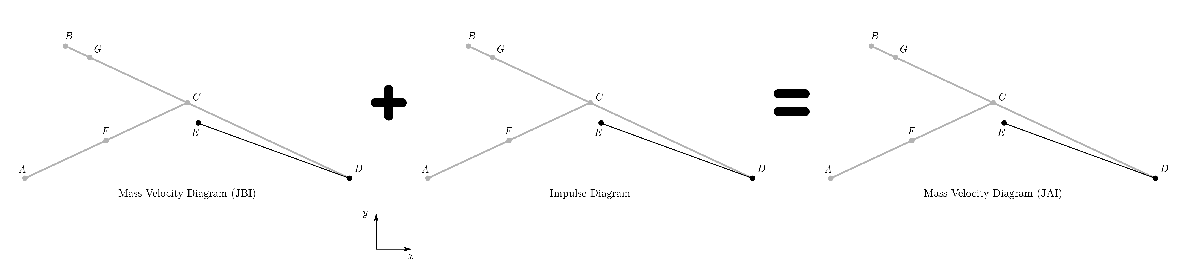


$$\begin{array}{rll}
\vec{H}_{D\,(JBI)} + \int_{JBI}^{JAI} M_D\, dt &= \vec{H}_{D\, (JAI)} & \\
\vec{H}_{D\,(JBI)} &= \vec{H}_{D\, (JAI)} & \text{(3)}
\end{array}$$


## Solution Approach

Setting up and solving the three equations derived above requires many more than three intermediate equations. First, the system kinematics must be analyzed, both before impact and after impact. Next, the moments must be calcualted using the principle of impulse and momentum. Fortunately, all of these relationships are linear and can be expressed as matrix equations that can be solved using MATLAB.

In the following analysis the derivative of the state vector will be referred to simply as the "velocity vector" and represented by the symbol $\mathbf{\dot{x}}$. An intermediate variable will be defined as $\mathbf{\dot{\chi}}$ and referred to as the "augmented velocity vector". The velocity vector, $\mathbf{\dot{x}}$, contains only the angular velocities for each link, but the augmented velocity vector, $\mathbf{\dot{\chi}}$, contains the linear velocities as well. Explicitly, $\mathbf{\dot{x}} = 
\left[\begin{array}{ccc}
\dot\theta_1 &
\dot\theta_2 &
\dot\theta_3
\end{array}\right]^\top$, and $\mathbf{\dot{\chi}} = 
\left[\begin{array}{ccccccccc}
\dot\theta_1 &
\dot\theta_2 &
\dot\theta_3 &
\dot x_1 &
\dot y_1 &
\dot x_2 &
\dot y_2 &
\dot x_3 &
\dot y_3
\end{array}\right]^\top$.

The system kinematics can be analyzed using the vector loop method. Using the vector loop method, matrices $A$ and $B$ can be determined that will relate the velocity vector $\mathbf{\dot{x}}$ containing only angular velocites, to an augmented velocity vector $\mathbf{\dot{\chi}}$ containing the angular velocities and linear velocities for the JBI and JAI cases respectively.

### Kinematics JBI

Before impact, point D is fixed in contact with the ground.


$$\begin{array}{rl}
\mathbf{\dot{\chi}}_{JBI} &= A \mathbf{\dot{x}}_{JBI} & \\
\left[\begin{array}{rll}
\dot\theta_1 \\
\dot\theta_2 \\
\dot\theta_3 \\
\dot x_1 \\
\dot y_1 \\
\dot x_2 \\
\dot y_2 \\
\dot x_3 \\
\dot y_3
\end{array}\right]_{JBI} &=
\left[\begin{array}{rl}
A_{11} & A_{12} & A_{13} \\
A_{21} & A_{22} & A_{23} \\
A_{31} & A_{32} & A_{33} \\
A_{41} & A_{42} & A_{43} \\
A_{51} & A_{52} & A_{53} \\
A_{61} & A_{62} & A_{63} \\
A_{71} & A_{72} & A_{73} \\
A_{81} & A_{82} & A_{83} \\
A_{91} & A_{92} & A_{93} 
\end{array}\right] 
\left[\begin{array}{rl}
\dot\theta_1 \\
\dot\theta_2 \\
\dot\theta_3 
\end{array}\right]_{JBI}  & \text{(4)}
\end{array}$$


### Kinematics JAI

After impact, point A is fixed in contact with the ground.


$$\begin{array}{rl}
\mathbf{\dot{\chi}}_{JAI} &= B \mathbf{\dot{x}}_{JAI} & \\
\left[\begin{array}{rll}
\dot\theta_1 \\
\dot\theta_2 \\
\dot\theta_3 \\
\dot x_1 \\
\dot y_1 \\
\dot x_2 \\
\dot y_2 \\
\dot x_3 \\
\dot y_3
\end{array}\right]_{JAI} &=
\left[\begin{array}{rl}
B_{11} & B_{12} & B_{13} \\
B_{21} & B_{22} & B_{23} \\
B_{31} & B_{32} & B_{33} \\
B_{41} & B_{42} & B_{43} \\
B_{51} & B_{52} & B_{53} \\
B_{61} & B_{62} & B_{63} \\
B_{71} & B_{72} & B_{73} \\
B_{81} & B_{82} & B_{83} \\
B_{91} & B_{92} & B_{93} 
\end{array}\right] 
\left[\begin{array}{rl}
\dot\theta_1 \\
\dot\theta_2 \\
\dot\theta_3 
\end{array}\right]_{JAI}  & \text{(5)}
\end{array}$$


### Summation of Moments

With the augmented velocity vectors defined, before and after impact, the angular momentum can be determined. Consider a vector $\mathbf{H}$, which contains the values of angular momentum that are conserved during impact. That is:


$$\mathbf{H} = 
\left[ \begin{array}{c}
H_A \\
H_C \\
H_D
\end{array} \right] ~~
\begin{array}{l}
\text{(Link 1, Link 2, and Link 3)} \\
\text{(Link 2 and Link 3)} \\
\text{(Link 3)}
\end{array}$$


The vector $\mathbf{H}$ can be related to the augmented velocity vector using another matrix $M$.


$$\begin{array}{rl}
\mathbf{H} &= M \mathbf{\dot{\chi}} & \\
\left[\begin{array}{rll}
H_A \\
H_B \\
H_C
\end{array}\right] &=
\left[\begin{array}{ccccccccc}
M_{11} & M_{12} & M_{13} & M_{14} & M_{15} & M_{16} & M_{17} & M_{18} & M_{19} \\
M_{21} & M_{22} & M_{23} & M_{24} & M_{25} & M_{26} & M_{27} & M_{28} & M_{29} \\
M_{31} & M_{32} & M_{33} & M_{34} & M_{35} & M_{36} & M_{37} & M_{38} & M_{39}
\end{array}\right] 
\left[\begin{array}{rl}
\dot\theta_1 \\
\dot\theta_2 \\
\dot\theta_3 \\
\dot{x}_1 \\
\dot{y}_1 \\
\dot{x}_2 \\
\dot{y}_2 \\
\dot{x}_3 \\
\dot{y}_3
\end{array}\right]_{JAI}  & \text{(6)}
\end{array}$$


Equation 1 through Equation 6 can be combined and solved to relate the velocity vector after impact, $\mathbf{\dot{x}}_{JAI}$, to the velocity vector before impact, $\mathbf{\dot{x}}_{JBI}$.


$$\begin{array}{rll}
\mathbf{H}_{JBI} &= \mathbf{H}_{JAI} & \\
M\,\mathbf{\dot{\chi}}_{JBI} &= M\,\mathbf{\dot{\chi}}_{JAI} & \\
M\, B\, \mathbf{\dot{x}}_{JBI} &= M\, A\, \mathbf{\dot{x}}_{JAI} & \\
\mathbf{\dot{x}}_{JAI} &= \left( M\,B \right)^{-1} M\, A\, \mathbf{\dot{x}}_{JBI}  & (7)
\end{array}$$


So, to find $\mathbf{\dot{x}}_{JAI}$, all that needs to be done is to define the matrices $A$, $B$, and $M$ and then to solve Equation 7 using MATLAB . None of the equations need to be solved by hand.

## Matlab Implementation

This function takes in the following parameters

    `x_JBI`             The state vector just before impact

    `x_dot_JBI`     The velocity vector just before impact

    `P`                     A MATLAB struct containing all of the constant parameters

The function returns the following parameters

    `x_JAI`             The state vector just after impact

    `x_dot_JAI`     The velocity vector just after impact

function [x_jai, x_dot_jai] = jbi2jai(x_jbi, x_dot_jbi, P)

First, all the angles in the state vector are used to define the sin and cos terms used in $A$, $B$, and $M$.

th1 = x_jbi(1); s1 = sin(th1);  c1 = cos(th1);
th2 = x_jbi(2); s2 = sin(th2);  c2 = cos(th2);
th3 = x_jbi(3); s3 = sin(th3);  c3 = cos(th3);

Next, the $A$ matrix is defined.

A = [   1           0           0
        0           1           0
        0           0           1
        P.r_CF*s1  -P.r_CD*s2   0
       -P.r_CF*c1   P.r_CD*c2   0
        0          -P.r_DG*s2   0
        0           P.r_DG*c2   0
        0           0          -P.r_DE*s3
        0           0           P.r_DE*c3 ];

Then, the $B$ matrix is defined.

B = [   1           0           0                       
        0           1           0                       
        0           0           1                       
        -P.r_AF*s1  0           0                       
        P.r_AF*s1   0           0                       
        -P.r_AC*s1  -P.r_CG*c2  0                       
        P.r_AC*c1   -P.r_CG*s2  0                       
        -P.r_AC*s1  P.r_CD*c2   -P.r_DE*c3                       
        P.r_AC*c1   P.r_CD*s2   -P.r_DE*s3 ]; 

The definition for the $M$ matrix does not fit as well on screen so it will be filled in entry by entry.

M = zeros(3,9);
% Row 1 (moments about A for link 1, link 2, and link 3)
M(1,1) =  1;                                            % <------
% Row 2 (moments about C for link 2 and link 3)
M(2,2) =  1;                                            % <------
% Row 3 (moments about D for link 3)
M(3,3) =  1;                                            % <------

Finally, the state after impact is related to the state before impact. Because the impact occurs instantaneously, the state vector does not change.

x_jai     = x_jbi;

However, the velocity vector does change according to Equation 7 as defined above.

x_dot_jai = (M*B)\M*A*x_dot_jbi;
end